# **Rotordynamic and Vibration analysis for Rigid Base**

**Based on Rotordynamics Prediction in Engineering By Michel Lalanne and Guy Ferraris**

***code by Aidin Latifi ***

For a basic Rotor which is widely known as Jeffcott, general represetation is as follows:

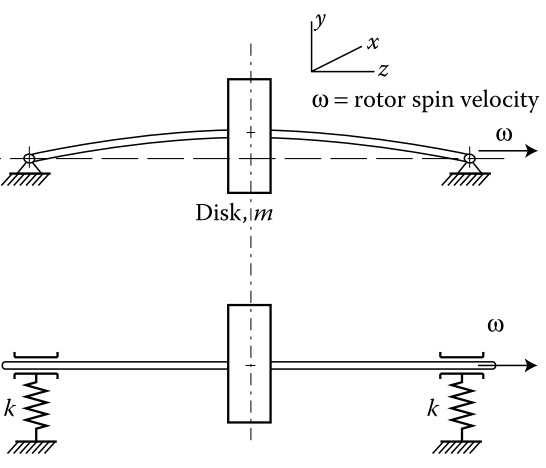

Each shaft element has two nodes and since each node has 4 degree of freedom, hence each shaft element has 8 degree of freedom which can be shown as below:


$$\delta ={{\left[u,\ v,\ \theta ,\ \varphi \right]}}^T$$


and for *i*th element of shaft:


$$\delta_i ={{\left[u_i ,\ v_i ,\ \theta_i ,\ \varphi_i ,\ u_{i+1} ,\ v_{i+1} ,\ \theta_{i+1} ,\ \varphi_{i+1} \right]}}^T$$


in the following code rotor is modeled using finite element method and number of nodes and the the length of rotor shaft can be manually changed in the following ***Edit Fields***:

*(there are two Rotor models prespecified as '****Compressor/turbine'**** and '****Jeffcott'**** which can be used by commenting each one of them Or Use the Drop Down menu)*

### Inputs


n = 11;                   % Number of total Nodes
L_tot = 6; % [m]       % Total length of shaft
L = L_tot/(n-1);             % Length Of each node
r_s = 0.1;              % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;
rotor = 'Jeffcott';
% rotor = 'Jeffcott';
% ============== SHAFT ================
pi = 3.1415;
S = pi*r_s^2;             % Shaft Cross section Area
I = pi*r_s^4/4;

if strcmp(rotor,'Compressor/turbine')
    n_shaft = 1:n-1;
    r_s_more = 1.4*[0.11 0.14 0.16 0.13 0.13 0.12 0.11 0.11 0.17 0.15 0.15 0.11 0.13 0.12 0.12 0.17 0.17 0.2 0.2];  % Shaft has variable diameter(manually adjustable)
elseif strcmp(rotor, 'Jeffcott')
    n_shaft = 1:n-1;
    r_s_more = 1.1*r_s*ones(1,n-1)
end
S_more = pi.*r_s_more.^2;
I_more = pi.*r_s_more.^4/4;
r_s_vec = r_s*ones(1,n);
I_vec = I*ones(1,n);
S_vec = S*ones(1,n);
size_n_shaf = size(n_shaft);
for i_shaf = 1:size_n_shaf(2)
    I_vec(1,n_shaft(i_shaf)) = I_more(i_shaf);
    S_vec(1,n_shaft(i_shaf)) = S_more(i_shaf);
    r_s_vec(1,n_shaft(i_shaf)) = r_s_more(i_shaf);
end

### Shaft

in the following code rotor shaft is modeled using finite element; thus for an element the mass matrix can be written as:

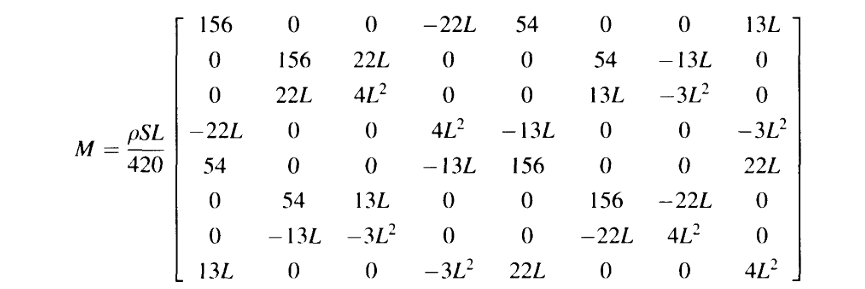

and

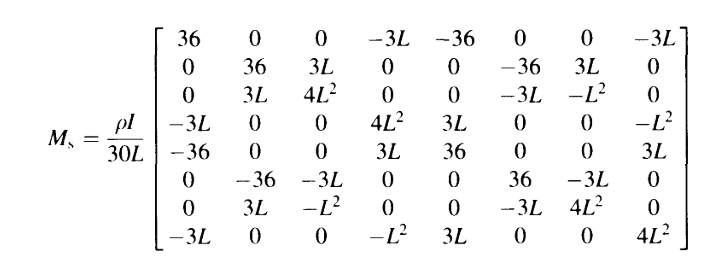

which are used in Lagrange's equation as follows:

M_ref = [156    0     0     -22*L   54    0     0      13*L;
    0      156   22*L   0      0     54   -13*L   0;
    0      22*L  4*L^2  0      0     13*L -3*L^2  0;
    -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
    54     0     0     -13*L   156   0     0      22*L;
    0      54    13*L   0      0     156  -22*L   0;
    0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
    13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_s = [36   0    0     -3*L   -36   0       0     -3*L;
    0    36   3*L    0      0   -36      3*L    0;
    0    3*L  4*L^2  0      0   -3*L    -L^2    0;
    -3*L  0    0      4*L^2  3*L  0       0     -L^2;
    -36   0    0      3*L    36   0       0      3*L;
    0   -36  -3*L    0      0    36     -3*L    0;
    0    3*L -L^2    0      0   -3*L     4*L^2  0;
    -3*L  0    0     -L^2    3*L  0       0      4*L^2]*rho_s*I/(30*L)

After calculating M_ref and M_s mass matrices in order to add them together to form the total mass matrix of the whole shaft we need to consider the fact that each element has a common node, sharing with neighboring element. The following method should be implemented for this cause:

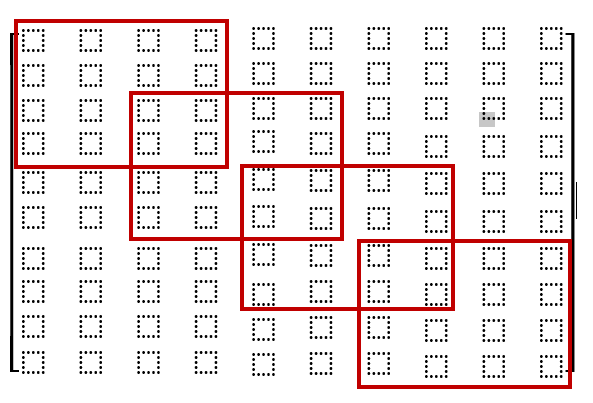

above representation is a schematic of a two dof rotor, which each of the red square is *M_ref+M_s* for each element. the part which is common between the two consecutive elements are added up.

M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + S_vec(k+1)*M_ref(1+i,1+j)/S +  I_vec(k+1)*M_s(1+i,1+j)/I;
            end
        end
    end
end
M

### Disk

In this context Disk is modeled as Rigid and also treated as point mass, therefore it only applies to a single node.

according to Lalanne book, Disk mass and Coriolis matrix can be modeled as below:

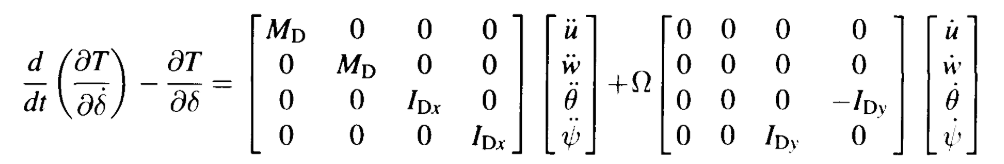

% ============== DISK ================
D_d = 3.0;                                 % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.15;                                 % Disk Width
rho_d = 7800;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d^2;  % Disk Inertia
I_Dy = 0.5*M_D*r_d^2;
if strcmp(rotor,'Compressor/turbine')
    n_dis = [4 5 6 7 8 17 18 19];
    r_d_more = [1.7 1.5 1.4 1.3 1.2 1 1.1 1.2];
    b_d_more = [0.17 0.15 0.14 0.13 0.12 0.1 0.12 0.14];
elseif strcmp(rotor,'Jeffcott')
    n_dis = round(n/2);
    r_d_more = 0.7;
    b_d_more = 0.2;
end
D_d_more = r_d_more*2;

V_d_more = b_d_more.*pi.*D_d_more.^2/4;
M_D_more = rho_d.*V_d_more;
I_Dx_more = 0.25*M_D_more.*r_d_more.^2  +  (1/12)*M_D_more.*b_d_more.^2;
I_Dy_more =  0.5*M_D_more.*r_d_more.^2;

I_Dx_vec = zeros(1,n);
I_Dy_vec = zeros(1,n);
r_d_vec = zeros(1,n);
b_d_vec = zeros(1,n);
size_n_dis = size(n_dis);
for i_disk = 1:size_n_dis(2)
    I_Dx_vec(1,n_dis(i_disk)) = I_Dx_more(i_disk);
    I_Dy_vec(1,n_dis(i_disk)) = I_Dy_more(i_disk);
    r_d_vec(1,n_dis(i_disk)) = r_d_more(i_disk);
    D_d_vec = r_d_vec*2;
    b_d_vec(1,n_dis(i_disk)) = b_d_more(i_disk);
    V_d_vec = pi*b_d_vec.*D_d_vec.^2/4;
    M_D_vec = rho_d.*V_d_vec;
end
for p = 1:n
    M_disk = [M_D_vec(p);M_D_vec(p);I_Dx_vec(p);I_Dx_vec(p)].*eye(4);
    for i = 0:3
        for j = 0:3
            M(1+(p-1)*4+i,1+(p-1)*4+j)= M(1+(p-1)*4+i,1+(p-1)*4+j) + M_disk(1+i,1+j);
        end
    end
    
end

% n_d = [round(n/2)];                                   % Number Of Node(s) Which Disk is Located
% M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix
% for n_disk = n_d
%     k = n_disk - 1;
%     if 1+k*4 < n*4
%         for i = 0:3
%             for j = 0:3
%                 M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
%             end
%         end
%     end
% end


% ============== SHAFT AND DISK DAMPING ================
C_disk = [0 0 0    0;
    0 0 0    0;
    0 0 0   -I_Dy;
    0 0 I_Dy 0]*omega;

C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
    36   0    0     -3*L   -36   0       0     -3*L;
    3*L  0    0     -4*L^2 -3*L  0       0      L^2;
    0    3*L  4*L^2  0      0   -3*L    -L^2    0;
    0    36   3*L    0      0   -36      3*L    0;
    -36   0    0      3*L    36   0       0      3*L;
    3*L  0    0      L^2   -3*L  0       0     -4*L^2;
    0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+I_vec(k+1)*C_ref(1+i,1+j)/I;
            end
        end
    end
end
% for k = 0:n
%     if 1+k*4 < n*4 - n
%         for i = 0:7
%             for j = 0:7
%                 C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
%             end
%         end
%     end
% end
for k = 0:n
    if 1+k*4 < n*4 - 8
        C_disk = [0 0 0             0;
            0 0 0             0;
            0 0 0            -I_Dy_vec(k+1);
            0 0 I_Dy_vec(k+1) 0]*omega;
        
        for i = 0:3
            for j = 0:3
                C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
            end
        end
    end
end
% for n_disk = n_d
%     k = n_disk - 1;
%     if 1+k*4 < n*4
%         for i = 0:3
%             for j = 0:3
%                 C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
%             end
%         end
%     end
% end
% ============== SHAFT STIFFNESS ================
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
    0    12   6*L       0         0     -12    6*L       0;
    0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
    -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
    -12   0    0         6*L       12     0     0         6*L;
    0   -12  -6*L       0         0      12   -6*L       0;
    0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
    -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

F = 1;
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
    0    36   3*L    0      0   -36      3*L    0;
    0    3*L  4*L^2  0      0   -3*L    -L^2    0;
    -3*L  0    0      4*L^2  3*L  0       0     -L^2;
    -36   0    0      3*L    36   0       0      3*L;
    0   -36  -3*L    0      0    36     -3*L    0;
    0    3*L -L^2    0      0   -3*L     4*L^2  0;
    -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                K(1+k*4+i,1+k*4+j) = K(1+k*4+i,1+k*4+j) + I_vec(k+1)*K_C(1+i,1+j)/I + K_F(1+i,1+j);
            end
        end
    end
end

%% ============== BEARINGS AND SEALS ================
kxx=8e7;
kxz=-1e7;
kzx=-6e7;
kzz=10e7;
cxx=8e3;
cxz=-3e3;
czx=-3e3;
czz=12e3;
K_bearing =-[kxx 0 kxz 0;
    0   0 0   0;
    kzx 0 kzz 0;
    0   0 0   0];

C_bearing =-[cxx 0 cxz 0;
    0   0 0   0;
    czx 0 czz 0;
    0   0 0   0];


*Note: position of the bearings can be adjusted manually in the following ****Edit Field***

n_bearings = [1 n];

for bearing = n_bearings
    k = bearing - 1;
    %     if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            K(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
        end
    end
    %     end
    k = bearing - 1;
    %     if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
        end
    end
    %     end
end

% for k = 1:4:n*4
%     % Shaft
%     node = plot(L*round(k/4) + zeros(1,3) ,[-r_s 0 r_s],'r-');
%     hold on
%     shaft = plot([L*round(k/4) L*round(k/4)+L] , r_s*ones(1,2),'black');
%     plot([L*round(k/4) L*round(k/4)+L] , -r_s*ones(1,2),'black')
%     % Disk
% end
% for n_disk = n_d
%     disk = plot((n_disk*L-b_d/2)*ones(1,3), [-r_d 0 r_d],'blue');
%     plot((n_disk*L+b_d/2)*ones(1,3), [-r_d 0 r_d],'blue')
%     plot([n_disk*L-b_d/2 n_disk*L+b_d/2] , r_d*ones(1,2),'blue')
%     plot([n_disk*L-b_d/2 n_disk*L+b_d/2] , -r_d*ones(1,2),'blue')
% end

### Rotor 2D Diagram

Using Disk and Shaft data a 2D Diagram can be created for visual understanding and also debugging. 

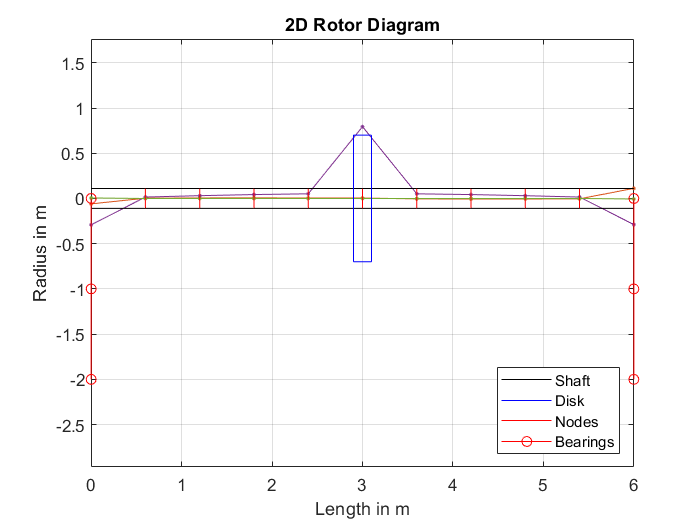

%% ============== 2D Rotor Diagram ==============
for k = 1:4:(n-1)*4
    if round(k/4) > 0
        if r_s_vec(round(k/4)+1) <= r_s_vec(round(k/4))
            node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)) 0 r_s_vec(round(k/4))],'r-');
        else
            node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)+1) 0 r_s_vec(round(k/4)+1)],'r-');
        end
    end
%     node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)+1) 0 r_s_vec(round(k/4)+1)],'r-');
    hold on
    shaft = plot([L*round(k/4) L*round(k/4)+L] , r_s_vec(round(k/4)+1)*ones(1,2),'black');
    plot([L*round(k/4) L*(round(k/4)+1)] , -r_s_vec(round(k/4)+1)*ones(1,2),'black')
end
for k = 1:4:n*4
    if r_d_vec(round(k/4)+1) ~= 0
        disk = plot((L*round(k/4) - b_d_vec(round(k/4)+1)/2)*ones(1,3) ,[-r_d_vec(round(k/4)+1) 0 r_d_vec(round(k/4)+1)],'blue');
        plot((L*round(k/4) + b_d_vec(round(k/4)+1)/2)*ones(1,3) ,[-r_d_vec(round(k/4)+1) 0 r_d_vec(round(k/4)+1)],'blue');
        plot([(L*round(k/4) - b_d_vec(round(k/4)+1)/2) (L*round(k/4) + b_d_vec(round(k/4)+1)/2)] ,r_d_vec(round(k/4)+1)*ones(1,2),'blue');
        plot([(L*round(k/4) - b_d_vec(round(k/4)+1)/2) (L*round(k/4) + b_d_vec(round(k/4)+1)/2)] ,-r_d_vec(round(k/4)+1)*ones(1,2),'blue');
    end
end
% Bearings
for bearing = n_bearings -1
    bearings = plot(round(bearing*ones(1,3)*L) ,[-20*r_s -10*r_s 0],'ro-');
    ylabel('Radius in m')
    xlabel('Length in m')
    title('2D Rotor Diagram')
    legend([shaft, disk, node, bearings],{'Shaft', 'Disk','Nodes', 'Bearings'},'Location','southeast');
    grid on
end
axis equal

% hold off

### Soution of Equations

In order to find and measure;

- Natural Frequencies

- Campbell Diagram

- Mode shapes

Rotor's Equation Of Motion(EOM) and the corresponding Eigenvalues and Eigenvectors need to be calculated. hence using the Direct Method in Lalanne's Book results the following expression:

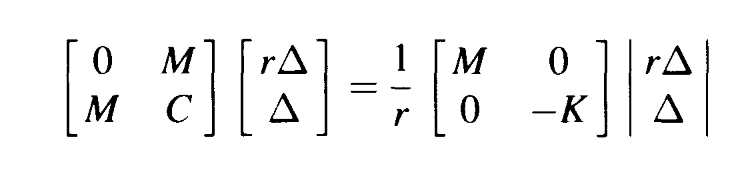

and implementing furthur simplification:

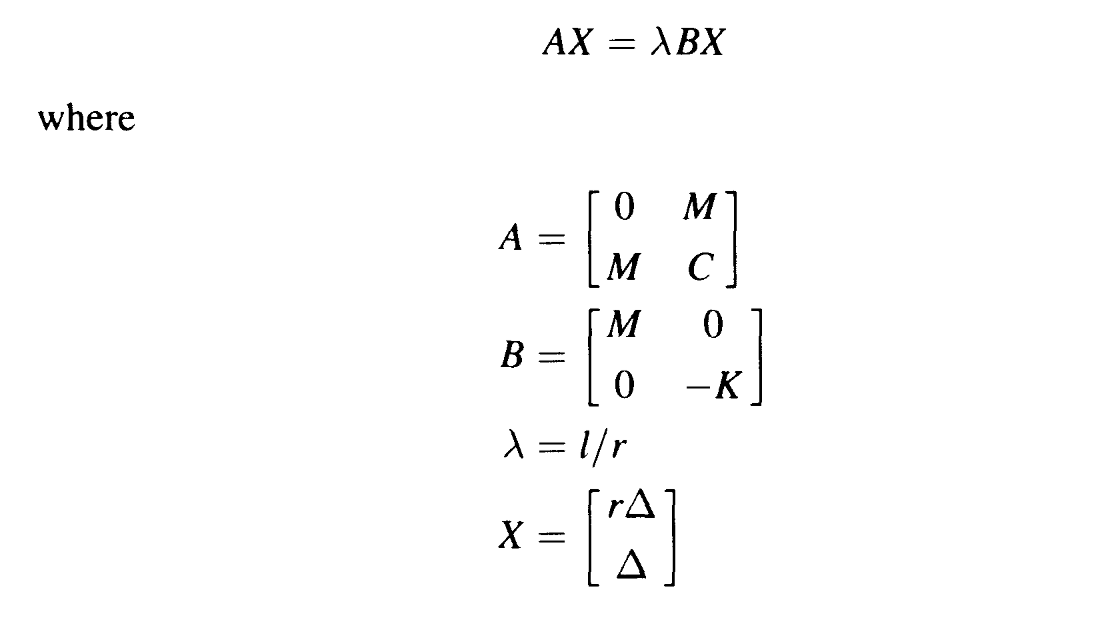

syms omega
assume(omega,'real')
C = C*omega;

syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C];
B = [M  zeros(n*4);zeros(n*4)  -K];
clear w
test_A = vpa(A,2);
test_B = vpa(B,2);
omega = 300;
test_A_new = subs(test_A,'omega',omega);
[V_new,D_new]=eig(test_A_new*pinv(test_B));   % pinv (Moore-Penrose Pseudoinverse) pinv treats singular values of A that are smaller than the tolerance as zero So to prevent rank deficiency
[D_new_sorted,ind] = sort(diag(D_new),'ascend')
w_sorted = sort(imag(1./diag(D_new)),'ascend')
w(:,round(omega/50) + 1) = w_sorted;
F = w./(2*pi);
V_new_sorted = V_new(:,ind);


r = diag(1./D_new);
R = real(V_new);
I = imag(V_new);
omeg = imag(r);
realr = real(r);

### Mode Shapes

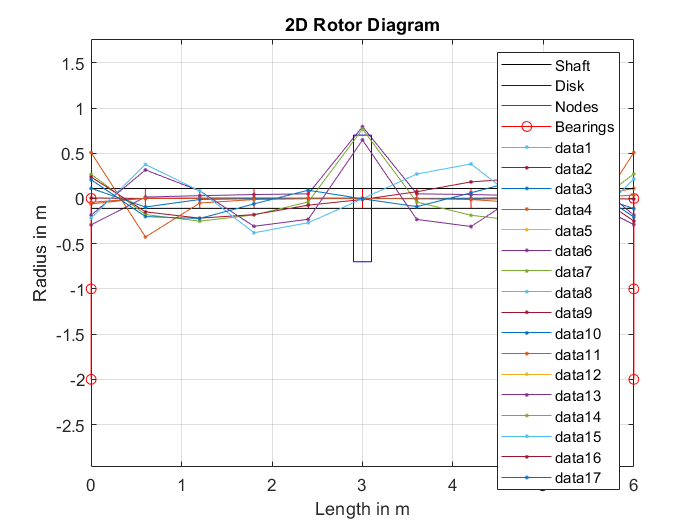

for i=10:20
    % for k = 1:4:n*4
    %     z = L*round(k/4)
    %     plot(z,R(k,i),'r.-')
    %     hold on
    % end
    
    plot(L*round((1:4:n*4)/4),R((1:4:n*4)+n*4,i),'.-')
    hold on
    grid on
end

% hold off

% u_v_Part_CodeExtension

clear z u v u_1 v_1 phi theta
C = sym('C',[n*8 1]);
temp = sym('temp',[n*8 1]);
syms t

i = 5;     % mode shape number for the specific rotor frequency
% Initial Conditions:
q_0_1_u = 0.1*rand(1,2*n);
q_dot_0_1_u = zeros(1,2*n);
q_0_1_v = zeros(1,2*n);
q_dot_0_1_v = -omeg(i)*q_0_1_u;
%
for k = 1:4:n*4*2
    C = sym('C',[n*8 1]);
    syms t
    j = 1;
    u_1 = (C(j)*R(k,i)*cos(omeg(i)*t) - C(j+1)*I(k,i)*sin(omeg(i)*t));   % u_1 is a temporary variable to store u displacement in every node and then rewrite.
    diff_u_1 = -realr(i)*(C(j)*R(k,i)*cos(omeg(i)*t) - C(j+1)*I(k,i)*sin(omeg(i)*t)) + (-C(j)*R(k,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k,i)*omeg(i)*cos(omeg(i)*t));
    
    u_1_0 = subs(u_1,'t',0);
    diff_u_1_0 = subs(diff_u_1,'t',0);
    
    eqn_1 = q_0_1_u(1,round(k/4)+1) == u_1_0;
    eqn_2 = q_dot_0_1_u(1,round(k/4)+1) == diff_u_1_0;
    check_u_1_0 = jacobian(u_1_0,[C(j) C(j+1)])
    if check_u_1_0(1) ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    check_diff_u_1_0 = jacobian(diff_u_1_0,[C(j+1)])
    if check_diff_u_1_0(1) ~= 0
        eqn_2 = subs(eqn_2,'C1',C(j));
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1) = 0;
    end
    
    u_1 = subs(u_1,'C1',C(j));
    u_1 = subs(u_1,'C2',C(j+1));
    diff_u_1 = subs(diff_u_1,'C1',C(j));
    diff_u_1 = subs(diff_u_1,'C2',C(j+1));
    t=0:0.001:3;
    u_1 = subs(u_1,'t',t);
    u(round(k/4)+1 ,:) = u_1;
    
    diff_u_1 = subs(diff_u_1,'t',t);
    diff_u(round(k/4)+1 ,:) = diff_u_1;
    
    syms t
    j = 3;
    v_1 = (C(j)*R(k+1,i)*cos(omeg(i)*t) - C(j+1)*I(k+1,i)*sin(omeg(i)*t));   % v_1 is a temporary variable to store v displacement in every node and then rewrite.
    diff_v_1 = -realr(i)*(C(j)*R(k+1,i)*cos(omeg(i)*t) - C(j+1)*I(k+1,i)*sin(omeg(i)*t)) + (-C(j)*R(k+1,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+1,i)*omeg(i)*cos(omeg(i)*t));
    v_1_0 = subs(v_1,'t',0);
    diff_v_1_0 = subs(diff_v_1,'t',0);
    
    eqn_1 = q_0_1_v(1,round(k/4)+1) == v_1_0;
    eqn_2 = q_dot_0_1_v(1,round(k/4)+1) == diff_v_1_0;
    
    check_v_1_0 = jacobian(v_1_0,[C(j) C(j+1)])
    if check_v_1_0(1) ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    check_diff_v_1_0 = jacobian(diff_v_1_0,[C(j+1)])
    if check_diff_v_1_0(1) ~= 0
        eqn_2 = subs(eqn_2,'C3',C(j));
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1) = 0;
    end
    
    v_1 = subs(v_1,'C3',C(j));
    v_1 = subs(v_1,'C4',C(j+1));
    diff_v_1 = subs(diff_v_1,'C3',C(j));
    diff_v_1 = subs(diff_v_1,'C4',C(j+1));
    t=0:0.001:3;
    v_1 = subs(v_1,'t',t);
    % plot(t,v_1)
    v(round(k/4)+1,:) = v_1;
    
    diff_v_1 = subs(diff_v_1,'t',t);
    diff_v(round(k/4)+1 ,:) = diff_v_1;
    % plot(v_1,u_1)
    
    % if v_1_0 == 0
    %     v(round(k/4)+1 ,:) = zeros(1,3001);
    % end
    % for i = 1:3001/2
    %     plot(v_1(i),u_1(i),'r*')
    %     hold on
    %     pause(0.5)
    % end
    %     z + u(k,1:3001)*cos(R(k+2,i)+sqrt(-1)*I(k+2,i));
    %     z = round(k/4)+ones(1,3001) + u_1*cos(R(k+2,i)+sqrt(-1)*I(k+2,i)) + v_1*cos(R(k+3,i)+sqrt(-1)*I(k+3,i));
    z = round(k/4)+ones(1,3001);
    z_ref(round(k/4)+1,:) = z;
    plot3(real(z),v(round(k/4)+1,:),u(round(k/4)+1,:),'b.')
    plot3(z_ref(round((1:4:n*4)/4)+1,:),v(round((1:4:n*4)/4)+1+n,:),u(round((1:4:n*4)/4)+1+n,:),'b.')
    hold on
    plot3(real(z(1,1)),v(round(k/4)+1,1),u(round(k/4)+1,1),'r*')
    plot3(real(z(1,3)),v(round(k/4)+1,5),u(round(k/4)+1,5),'g*')
    grid on
    
    % view([180 0])
end
% plot3(z_ref(:,1),1*v(:,1),1*u(:,1),'r*')
axis equal
hold off

% theta_phi_Part_CodeExtension
clear z
i=5
for k = 1:4:n*4
    C = sym('C',[n*8 1]);
    size_q = size(q_0_1_u)
    syms t
    j = 5
    if round(k/4)+2 > size_q(2)
        q_0_1_u(round(k/4)+2) = 0;
        q_dot_0_1_u(round(k/4)+2) = 0;
    end
    q_0_1_phi = atan((q_0_1_u(round(k/4)+2) - q_0_1_u(round(k/4)+1))/L);
    q_dot_0_1_phi = atan((q_dot_0_1_u(round(k/4)+2) - q_dot_0_1_u(round(k/4)+1))/L);
    
    phi_1 = (C(j)*R(k+2,i)*cos(omeg(i)*t) - C(j+1)*I(k+2,i)*sin(omeg(i)*t));
    diff_phi_1 = -realr(i)*(C(j)*R(k+2,i)*cos(omeg(i)*t) - C(j+1)*I(k+2,i)*sin(omeg(i)*t)) + (-C(j)*R(k+2,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+2,i)*omeg(i)*cos(omeg(i)*t));
    
    phi_1_0 = subs(phi_1,'t',0);
    diff_phi_1_0 = subs(diff_phi_1,'t',0);
    
    eqn_1 = q_0_1_phi == phi_1_0;
    eqn_2 = q_dot_0_1_phi == diff_phi_1_0;
    if phi_1_0 ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    eqn_2 = subs(eqn_2,'C5',C(j));
    diff_phi_1_0 = subs(diff_phi_1_0, 'C5',C(j));
    if diff_phi_1_0 ~= 0
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1)=0;
    end
    phi_1 = subs(phi_1,'C5',C(j));
    phi_1 = subs(phi_1,'C6',C(j+1));
    
    t=0:0.001:3;
    phi_1 = subs(phi_1,'t',t);
    phi(round(k/4)+1 ,:) = phi_1;
end

for k = 1:4:n*4
    C = sym('C',[n*8 1]);
    size_q = size(q_0_1_v)
    syms t
    j = 7
    if round(k/4)+2 > size_q(2)
        q_0_1_v(round(k/4)+2) = 0;
        q_dot_0_1_v(round(k/4)+2) = 0;
    end
    q_0_1_theta = atan((q_0_1_v(round(k/4)+2) - q_0_1_v(round(k/4)+1))/L);
    q_dot_0_1_theta = atan((q_dot_0_1_v(round(k/4)+2) - q_dot_0_1_v(round(k/4)+1))/L);
    
    theta_1 = (C(j)*R(k+3,i)*cos(omeg(i)*t) - C(j+1)*I(k+3,i)*sin(omeg(i)*t));
    diff_theta_1 = -realr(i)*(C(j)*R(k+3,i)*cos(omeg(i)*t) - C(j+1)*I(k+3,i)*sin(omeg(i)*t)) + (-C(j)*R(k+3,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+3,i)*omeg(i)*cos(omeg(i)*t));
    
    theta_1_0 = subs(theta_1,'t',0);
    diff_theta_1_0 = subs(diff_theta_1,'t',0);
    
    eqn_1 = q_0_1_theta == theta_1_0;
    eqn_2 = q_dot_0_1_theta == diff_theta_1_0;
    if theta_1_0 ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    
    eqn_2 = subs(eqn_2,'C7',C(j));
    
    diff_theta_1_0 = subs(diff_theta_1_0, 'C5',C(j));
    if diff_theta_1_0 ~= 0
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1)=0;
    end
    theta_1 = subs(theta_1,'C7',C(j));
    theta_1 = subs(theta_1,'C8',C(j+1));
    
    t=0:0.001:3;
    theta_1 = subs(theta_1,'t',t);
    theta(round(k/4)+1 ,:) = theta_1;
end
% for k = 1:4:n*4
%     z = round(k/4)+ones(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
% end
% for k = 1:4:n*4
%     z(round(k/4)+1,:) = round(k/4) + ones(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
%     plot3(z(round(k/4)+1,:),u(round(k/4)+1,:),v(round(k/4)+1,:))
%     hold on
% end
% hold off

for k = 1:4:n*4
    %     z(round(k/4)+1,:) = L*round(k/4) + zeros(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
    z(round(k/4)+1,:) = L*round(k/4) + zeros(1,3001) + u(round(k/4)+1 ,:).*sin(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*sin(theta(round(k/4)+1 ,:));
    %     z(round(k/4)+1,:) = L*round(k/4) + zeros(1,3001) + u(round(k/4)+1 ,:) + v(round(k/4)+1 ,:);
    for i = 1:3001/3
        plot3(z(round(k/4)+1,i),u(round(k/4)+1,i),v(round(k/4)+1,i),'r-')
        %         pause(0.05)
        grid on
        hold on
    end
    hold on
end
axis equal
hold off

% First Method === eigenvalue-eigenvector sorting ===
% This Code is to be used as an Extention to the MAIN Code

test_A = vpa(A,2);
test_B = vpa(B,2);
clear w F

stop = 2500;
mid = 500;
% start = 0 (always)
w = zeros(n*4*2,stop/mid);  % pre-allocation for faster computation

for omega= 0:mid:stop   % in rad/s
    test_A_new = subs(test_A,'omega',omega);
    %     [V_new,D_new]=eig(test_A_new/test_B);
    [V_new,D_new]=eig(test_A_new*pinv(test_B));
    sorted = sort(imag(1./diag(D_new)),'ascend');
    w(:,round(omega/mid) + 1) = sorted;
    F = w./(2*pi);
end
% [eigvector, eigvalue]=eig(A - (lan).*B)

omega= 0:mid:stop;
plot(omega,F(n*4:n*8,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
hold on
plot(omega,omega, '-.')
plot(omega,0.5*omega, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rad/s)')
ylabel('Frequency (Hz)')
hold off


% mass Unbalance Respose
e = r_d/4;
for omega = 0:50:2500
    F = M*e*omega^2;
    X(round(omega/50) + 1) = F*pinv(-M*omega^2+C*omega+K)
end
